# Semi quantitative mole fraction calculation

Load a workspace result of fitExcSpectrumImage.mlx for the concentration evaluation

% Author: Abbas El Moussawi
% COPYRIGHT 2024: EMPI-RF - University of Duisburg-Essen  
init;
fitResultsWS = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\exampleImagedSpectra\MATLAB_out\FOR0072\20240919-142520_fitResults.mat";
sameWS = true;
load(fitResultsWS);

% Required from a saved workspace, use fitExcSpectrumImage.mlx



fittedImageLine = fittedImage;


Load the temperature values from a different fit 

*(i.e. if another scan region for temperature evaluation is used)*

if ~sameWS
    fitResultsT = "D:\LIF-Measurements\Export\FOR0072\20240919-142520_fitResults.mat";
    load(fitResultsT, "fittedImage");
end

lines = cell(length(linelist), 1);

for l = 1:length(linelist)
    selectedLine = linelist{l};
    lines{l} = sprintf('Line %i: %s at %.2f 1/cm ', l, selectedLine.branch, selectedLine.nu0);

end
lines = string(lines);
TT = fittedImage(:,:,1);

Select line for evaluation 

L = lines(18); 
lIdx = find(lines==L);

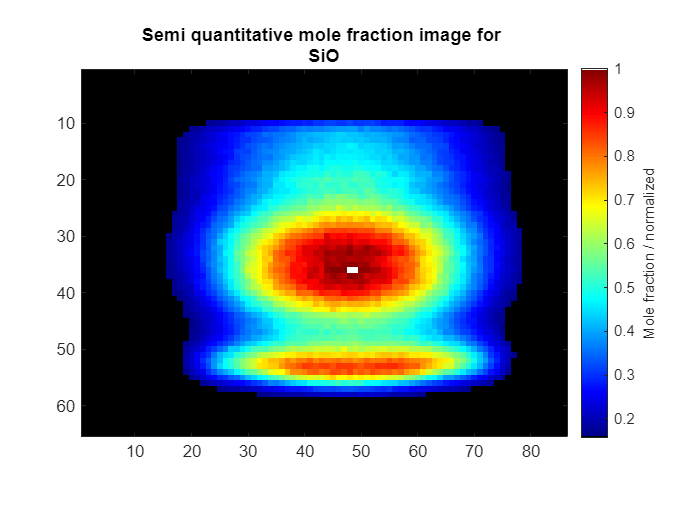

 


selectedLine = linelist{lIdx};

[h,w] = size(fitResidue);


xMolDist = zeros(h,w);


for i = 1:w
    for j = 1:h


        if isinf(TT(j,i)) || isnan (TT(j,i))

            xMolDist(j,i) = NaN;
            continue;
        end
        solutionValues = fittedImageLine(j,i,:);
        solutionValues(1) = TT(j,i);

        % restoring intensity at peak, since fitExcImageDataset normalizes spectra.
        lineIdx = abs(scan.wavenumbers-selectedLine.nu0-solutionValues(5));
        [~, lineIdx] = min(lineIdx);
        ss = images3d(j,i,:); ss = ss(:);
        solutionValues(4) = ss(lineIdx);

        xMolDist(j,i) = semiQuanMoleFraction(scan.wavenumbers, solutionValues(:), selectedLine, Z, MM, colls=colls, gas= gas,P=P);

    end
end

xMolDist = xMolDist./max(xMolDist(:));


f = figure;
imagesc(xMolDist)

axis image;
title(['Semi quantitative mole fraction image for ' scan.species])
colorbarJet(f, label='Mole fraction / normalized');